%  Load an image
filepath= "images\starfish_noise9.jpg";
disp(filepath)

images\starfish_noise9.jpg


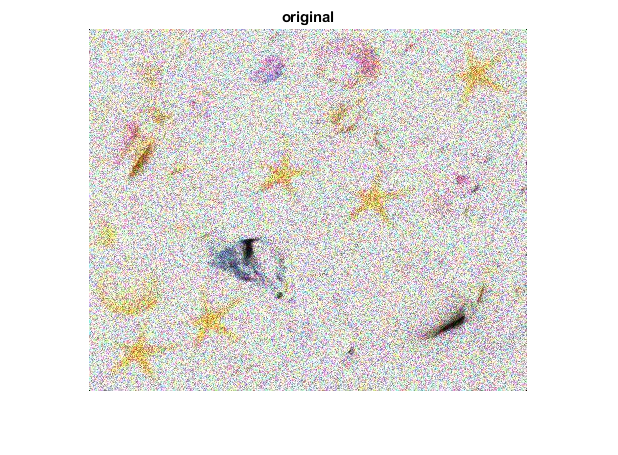

oIm = imread(filepath);
imshow(oIm);
title("original");

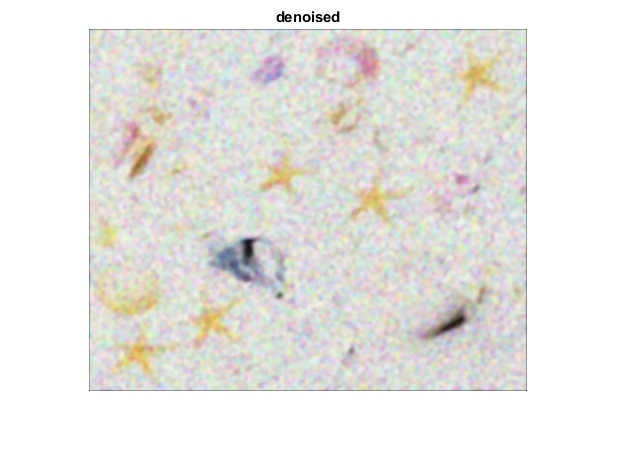


% % Denoise and enhance.
% Denoise the image.
im = oIm;
% im = DenoiseIsolated(im, 'medianfilter');
im = medfilt3(im, [5 5 1]);
im = imfilter(im, ones(3)/9, 'same');
imshow(im);
title("denoised");

LOW CONTRAST


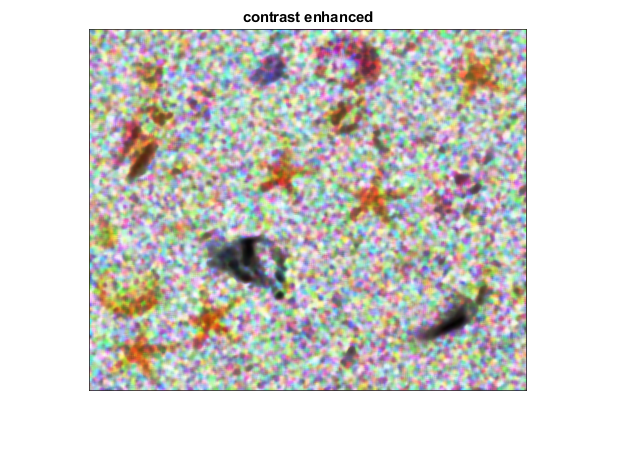

if(IsLowContrast(im))
    % Enhance the contrast.
    [c1,c2,c3] = imsplit(im);
    c1 = adapthisteq(c1);
    c2 = adapthisteq(c2);
    c3 = adapthisteq(c3);
%     c1 = imadjust(c1);
%     c2 = imadjust(c2);
%     c3 = imadjust(c3);
    im = cat(3, c1,c2,c3);
    imshow(im);
    title("contrast enhanced");
end

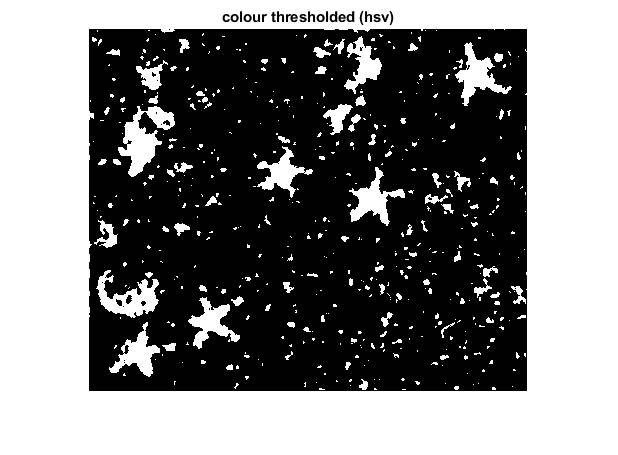


% Threshold the image in hsv and get a rough mask with candidate blobs.
mask = logical(Thresh(im));
imshow(mask);
title("colour thresholded (hsv)");

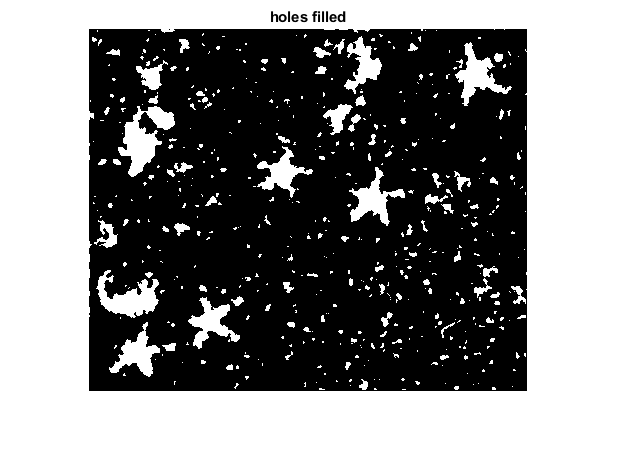


% % Morph.
% Fill holes of blobs.
mask = imfill(mask, 'holes');
imshow(mask);
title("holes filled");

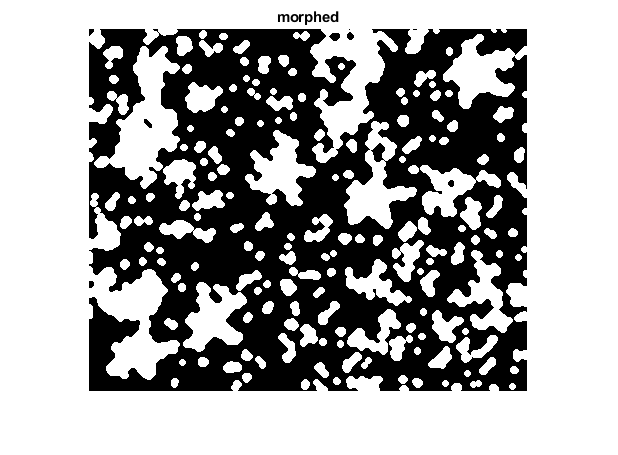

% Reduce candidates.
% Helps with the noiser images.
se = strel('diamond', 6);
mask = imclose(mask, se);
% General morph ops.
se = strel('line', 5, 45);
mask = imclose(mask, se);
se = strel('line', 5, 90);
mask = imclose(mask, se);
se = strel('line', 5, 135);
mask = imclose(mask, se);
se = strel('line', 5, 180);
mask = imclose(mask, se);

se = strel('line', 3, 45);
mask = imdilate(mask, se);
se = strel('line', 3, 90);
mask = imdilate(mask, se);
se = strel('line', 3, 135);
mask = imdilate(mask, se);
se = strel('line', 3, 180);
mask = imdilate(mask, se);

imshow(mask);
title("morphed");

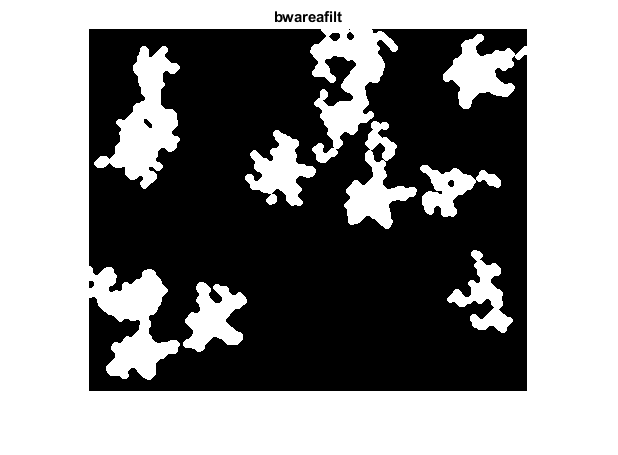


mask = bwareafilt(mask, [1500 1000000]);
imshow(mask);
title("bwareafilt");

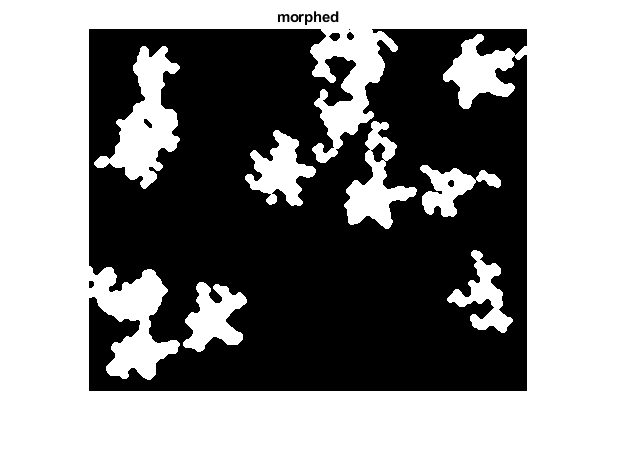


% se = strel('diamond', 1);
% mask = imclose(mask, se);

imshow(mask);
title("morphed");



% % % % % 
CC = bwconncomp(mask);
[cc, n] = bwlabel(mask);
properties_table = regionprops('table', mask, 'all')

properties_table = 9×30 table
    Area        Centroid                  BoundingBox                         SubarrayIdx              MajorAxisLength    MinorAxisLength    Eccentricity    Orientation     ConvexHull        ConvexImage       ConvexArea    Circularity         Image            FilledImage       FilledArea    EulerNumber      Extrema       EquivDiameter    Solidity    Extent      PixelIdxList         PixelList       Perimeter    PerimeterOld    MaxFeretDiameter    MaxFeretAngle    MaxFeretCoordinates    MinFeretDiame


eccentricity = properties_table.Eccentricity;
meanEcc = mean(eccentricity);
stdEcc = std2(eccentricity);
meanPlusStdEcc = meanEcc + stdEcc;
meanMinusStdEcc = meanEcc - stdEcc;
info = regionprops(cc,'Boundingbox') ; % Get region info from region propertieson properties
for k = 1 : n
    
    JroiX = imcrop(oIm, info(k).BoundingBox);
    tX = statxture(JroiX, 2);
%     id = CC.PixelIdxList(k)
    blobArea = properties_table.Area(k);
    ecc = eccentricity(k);
    if (ecc < 0.5)
        removeMask = cc == k;
        mask(removeMask) = 0;
        disp("Removed mask " + k)
    end
        disp(sprintf("Average gray level: %6.4f,\n" + ...
        "Average contrast: %6.4f,\n" + ...
        "Smoothness: %6.4f,\n" + ...
        "Third moment: %6.4f,\n" + ...
        "Uniformity: %6.4f,\n" + ...
        "Entropy: %6.4f,\n", tX(1), tX(2), tX(3), tX(4), tX(5), tX(6)));
end

Average gray level: 412.2607,
Average contrast: 78.3869,
Smoothness: 0.0462,
Third moment: -1.5386,
Uniformity: 0.0320,
Entropy: 13.6888,

Average gray level: 412.4841,
Average contrast: 78.6957,
Smoothness: 0.0465,
Third moment: -1.6681,
Uniformity: 0.0321,
Entropy: 13.6927,

Average gray level: 409.3130,
Average contrast: 81.0550,
Smoothness: 0.0493,
Third moment: -1.8160,
Uniformity: 0.0322,
Entropy: 13.7461,

Average gray level: 415.2183,
Average contrast: 76.5893,
Smoothness: 0.0441,
Third moment: -1.5153,
Uniformity: 0.0336,
Entropy: 13.5915,

Average gray level: 412.8269,
Average contrast: 75.4504,
Smoothness: 0.0428,
Third moment: -1.1050,
Uniformity: 0.0323,
Entropy: 13.6224,

Average gray level: 412.7959,
Average contrast: 77.4659,
Smoothness: 0.0451,
Third moment: -1.4646,
Uniformity: 0.0327,
Entropy: 13.6519,

Average gray level: 413.9193,
Average contrast: 74.4929,
Smoothness: 0.0418,
Third moment: -1.0020,
Uniformity: 0.0330,
Entropy: 13.5603,

Average gray level: 414.121


% %
% % chull = bwconvhull(im);
% % imshow(cc);
%

DrawRois(oIm, mask, 'r', 1, 'n');

9 objects detected


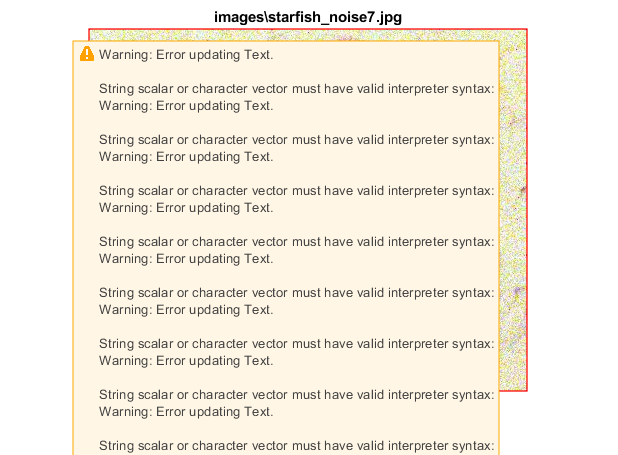

title(filepath);

% % MSER
% im = mask;
% regions = detectMSERFeatures(im);
% figure;
% imshow(im);
% hold on;
% plot(regions,'showPixelList',true,'showEllipses',false);

function diffMask = GetDiffMask(im, imP)
% Get mask of "isolated" noise.
imLnStd = log(std2(im))^2;
diff = abs(double(im) - double(imP));
diffMask = (diff > imLnStd);
end
% % % %


function noisePercent = GetRelPercentageNoise(im, noiseMask)
noisyPixels = sum(noiseMask(:));
nPx = numel(im);
noisePercent = (100/nPx) * noisyPixels;
end
% % % %


function [imP, noiseValue] = DenoiseIsolated(im, method)
maxPasses = 10;
changeThresh = 50;
dims = ndims(im);
repeat = true;
attempt = 0;


while (repeat && attempt < 3)
    attempt = attempt + 1; % try median and then try mean
    noiseValue = 100; % Reset
    passes = 0; % Reset
    repeat = false;
    imP = im;
    
    if (dims == 2)
        while(noiseValue > changeThresh && passes < maxPasses) % Repeat until change noise value is < thresh.
            [imP, noiseValue] = DenoiseIsolated2D(imP, method);
            passes = passes + 1;
        end
    elseif (dims == 3)
        while(noiseValue > changeThresh && passes < maxPasses) % Repeat until change noise value is < thresh.
            [imP, noiseValue] = DenoiseIsolated3D(imP, method);
            passes = passes + 1;
        end
    else
        error("Unsupported number of dimensions. Expected a 2D or 3D array.");
    end
    
    % Outputs in the range of 20-40 are resultant of noisy images benfitting from non-median filter techniques.
    %     if (noiseValue > 30)
    %         disp("Switching mode");
    %         method = "meanfilter";
    %         repeat = true;
    %     end
    % else finish.
end

disp("Method used: " + method);

%     imP = imsharpen(imP, 'amount', 2);
end
% % % %


function [imP, noiseValue] = DenoiseIsolated3D(im, method)
% Separate image channels.
[ch1, ch2, ch3] = imsplit(im);

% Denoise channels individually.
[dnCh1,noiseValue1] = DenoiseIsolated2D(ch1, method);
[dnCh2,noiseValue2] = DenoiseIsolated2D(ch2, method);
[dnCh3,noiseValue3] = DenoiseIsolated2D(ch3, method);

% Concatenate channels to create noise free image.
imP = cat(3, dnCh1, dnCh2, dnCh3);
noiseValue = mean([noiseValue1,noiseValue2,noiseValue3]);
end
% % % %


function [imP, noiseValue] = DenoiseIsolated2D(im, method)
% if s&p or isolated noise
if (method == "medianfilter")
    filtered = medfilt2(im, [5 5]); % [5 5] loses texture but keeps shape. [3 3] keeps texture but more noise.
elseif (method == "meanfilter")
    filtered = conv2(im, ones(3)/9, 'same');
end

diffMask = GetDiffMask(im, filtered);

% Swap noisy pixels for filtered ones
noise = (diffMask == 1);
imP = im;
imP(noise) = filtered(noise);

diffMask = GetDiffMask(im, imP);
noiseValue = GetRelPercentageNoise(im, diffMask);
imshow(diffMask)
title("Other noise value: " + round(noiseValue,2))
end
% % % %


function [BW,maskedRGBImage] = Thresh(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 09-May-2020
%------------------------------------------------------


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.863;
channel1Max = 0.192;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.400;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 1.000;

% Create mask based on chosen histogram thresholds
sliderBW = ( (I(:,:,1) >= channel1Min) | (I(:,:,1) <= channel1Max) ) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end

function bool = IsLowContrast(im)
% Low range or mean is > 200 || < 50 ;
RANGE = 75;
LOW = 40;
HIGH = 215;

theMin = min(im(:));
theMax = max(im(:));
theRange = theMax - theMin;
theMean = mean(im(:));
theStd = std2(im(:));
theMeanPStd = theMean + theStd;
theMeanMStd = theMean - theStd;
theRange2 = theMeanPStd - theMeanMStd;

bool = 0;
% if ((theRange <= RANGE) || (theMeanMStd > HIGH || theMeanPStd < LOW))
% if (theRange2 < RANGE && (theMeanMStd > HIGH || theMeanPStd < LOW))
if (theRange2 < RANGE || (theMeanMStd < LOW|| theMeanPStd > HIGH))
    % if ((theMeanMStd < LOW|| theMeanPStd > HIGH))
    bool = 1;
    disp("LOW CONTRAST");
end
%     theRange2
%     theMeanMStd
%     theMeanPStd
end
function stats = OverlayRois(imP, c, t, circle)
CC = bwconncomp(imP); % get "connected components" in the binary mask
% Uncomment to colour each segment randomly
% L = labelmatrix(CC);
% RGB = label2rgb(L,'cool','k','shuffle');
% imshow(RGB)

% Collate ALL region properties of each connect component (region)
stats = regionprops("table",CC,"all");

% DRAW BOUNDING BOXES AND GET BLOB COUNT
disp(CC.NumObjects + " objects detected") % Output text
info = regionprops(CC,'Boundingbox') ; % Get region info from region properties

% Draw bounding boxes for each region/connected component detected
for k = 1 : length(info)
    BB = info(k).BoundingBox; % get bounding box measures for region 'k'
    if circle == 'n'
        rectangle('Position', [BB(1),BB(2),BB(3),BB(4)],'EdgeColor',c,'LineWidth',t); % Draw roi as rectangle with colour c and line thickness t.
    else
        rectangle('Position', [BB(1),BB(2),BB(3),BB(4)],'EdgeColor',c,'LineWidth',t,"Curvature",[1,1]) ; % Draw roi as circle "
    end
end
end
% Simple facade for drawing rois on original image. c = colour of region
% outline, t = thickness, circle = 'y' or 'n' for circle or rect rois.
function stats = DrawRois(original, processed, c, t,circle)
figure
imshow(original)
stats = OverlayRois(processed, c, t, circle);
end
function t = statxture(f, scale)
%STATXTURE Computes statistical measures of texture in an image.
%   T = STATXURE(F, SCALE) computes six measures of texture from an
%   image (region) F. Parameter SCALE is a 6-dim row vector whose
%   elements multiply the 6 corresponding elements of T for scaling
%   purposes. If SCALE is not provided it defaults to all 1s.  The
%   output T is 6-by-1 vector with the following elements:
%     T(1) = Average gray level
%     T(2) = Average contrast
%     T(3) = Measure of smoothness
%     T(4) = Third moment
%     T(5) = Measure of uniformity
%     T(6) = Entropy

%   Copyright 2002-2004 R. C. Gonzalez, R. E. Woods, & S. L. Eddins
%   Digital Image Processing Using MATLAB, Prentice-Hall, 2004
%   $Revision: 1.5 $  $Date: 2004/11/04 22:33:43 $

if nargin == 1
    scale(1:6) = 1;
else % Make sure it's a row vector.
    scale = scale(:)';
end

% Obtain histogram and normalize it.
p = imhist(f);
p = p./numel(f);
L = length(p);

% Compute the three moments. We need the unnormalized ones
% from function statmoments. These are in vector mu.
[~, mu] = statmoments(p, 3); % Hole for the first variable.

% Compute the six texture measures:
% Average gray level.
t(1) = mu(1);
% Standard deviation.
t(2) = mu(2).^0.5;
% Smoothness.
% First normalize the variance to [0 1] by
% dividing it by (L-1)^2.
varn = mu(2)/(L - 1)^2;
t(3) = 1 - 1/(1 + varn);
% Third moment (normalized by (L - 1)^2 also).
t(4) = mu(3)/(L - 1)^2;
% Uniformity.
t(5) = sum(p.^2);
% Entropy.
t(6) = -sum(p.*(log2(p + eps)));

% Scale the values.
t = t.*scale;
end

function [v, unv] = statmoments(p,  n)
%STATMOMENTS Computes statistical central moments of image histogram.
%   [W, UNV] = STATMOMENTS(P, N) computes up to the Nth statistical
%   central moment of a histogram whose components are in vector
%   P. The length of P must equal 256 or 65536.
%
%   The program outputs a vector V with V(1) = mean, V(2) = variance,
%   V(3) = 3rd moment, . . . V(N) = Nth central moment. The random
%   variable values are normalized to the range [0, 1], so all
%   moments also are in this range.
%
%   The program also outputs a vector UNV containing the same moments
%   as V, but using un-normalized random variable values (e.g., 0 to
%   255 if length(P) = 2^8). For example, if length(P) = 256 and V(1)
%   = 0.5, then UNV(1) would have the value UNV(1) = 127.5 (half of
%   the [0 255] range).

%   Copyright 2002-2004 R. C. Gonzalez, R. E. Woods, & S. L. Eddins
%   Digital Image Processing Using MATLAB, Prentice-Hall, 2004
%   $Revision: 1.3 $  $Date: 2003/05/24 22:43:02 $

Lp = length(p);
if (Lp ~= 256) && (Lp ~= 65536)
    error('P must be a 256- or 65536-element vector.');
end
G = Lp - 1;

% Make sure the histogram has unit area, and convert it to a
% column vector.
p = p/sum(p); p = p(:);

% Form a vector of all the possible values of the
% random variable.
z = 0:G;

% Now normalize the z's to the range [0, 1].
z = z./G;

% The mean.
m = z*p;

% Center random variables about the mean.
z = z - m;

% Compute the central moments.
v = zeros(1, n);
v(1) = m;
for j = 2:n
    v(j) = (z.^j)*p;
end

if nargout > 1
    % Compute the uncentralized moments.
    unv = zeros(1, n);
    unv(1)=m.*G;
    for j = 2:n
        unv(j) = ((z*G).^j)*p;
    end
end
end % function